%% 1
syms x;
f = x^5+4*x^4-2*x^3-14*x^2-3*x-18;
result = factor(f);
disp(result);

$$\left(\begin{array}{cccc} x-2 & x^{2}+1 & x+3 & x+3 \end{array}\right)$$

%% 2_ab
syms y;
f = x.*exp(1).^(-x);
result = limit(f, x, Inf);
disp(result);

$$0$$


syms x;
f = tan(x)^(tan(2*x));
result = limit(f, x, pi/4);
disp(result);

$${\mathrm{e}}^{-1}$$

%% 3_ab
syms x
f = atan(x)/2-x/(2*(1+x^2)^2);
result = simplify(diff(f));
disp(result);

$$\frac{x^{2}\,\left(x^{2}+5\right)}{2\,{\left(x^{2}+1\right)}^{3}}$$


syms y
f = 3.*y.^4 - 14.*y.^3 + 12.*y.^2 + 24.*y + 6;
result = simplify(diff(f));
disp(result);

$$6\,\left(2\,y+1\right)\,{\left(y-2\right)}^{2}$$

%% 4_ab
syms x;
f = int(sqrt(1-x^2)/x^2);
result = simplify(vpa(f));
disp(result);

$$-\frac{1.0\,\left(\sqrt{1.0-x^{2}}+x\,\mathrm{asin}\left(x\right)\right)}{x}$$


syms y;
f = int(1./(sin(x).^3));
result = simplify(vpa(f));
disp(result);

$$0.5\,\log\left(\tan\left(0.5\,x\right)\right)-\frac{0.5\,\cos\left(x\right)}{{\sin\left(x\right)}^{2}}$$

%% 5_ac
syms x;
syms k;
s = symsum(1/(x^k), k, 0, inf);
disp(s);

$$\left\{ \begin{array}{cl} \frac{x}{x-1} & \text{ if }1<\left|x\right|\\ \infty & \text{ if }\left(\left|x\right|\in \left(0,1\right)\wedge x\in \left(0,1\right]\right)\vee x=1\\ -\frac{x\,\left(\left(\lim_{k\to \infty }\frac{1}{x^{k}}\right)-1\right)}{x-1} & \text{ if }\left(\left(\left|x\right|=1\wedge 0\leq x\right)\vee \left(\left|x\right|\in \left(0,1\right)\wedge x\notin \left(0,1\right)\right)\right)\wedge x\neq 1 \end{array}\right.$$


syms y;
syms n;
s = symsum(x.^n, n, 0, inf);
disp(s);

$$\left\{ \begin{array}{cl} \infty & \text{ if }1\leq x\\ -\frac{1}{x-1} & \text{ if }\left|x\right|<1 \end{array}\right.$$

%% 6
syms a;
a = 0;
syms n;
n = 5;
syms x;
f = exp(x);
result = taylor(f, 'ExpansionPoint', a, 'Order', n);
disp(result);

$$\frac{x^{4}}{24}+\frac{x^{3}}{6}+\frac{x^{2}}{2}+x+1$$

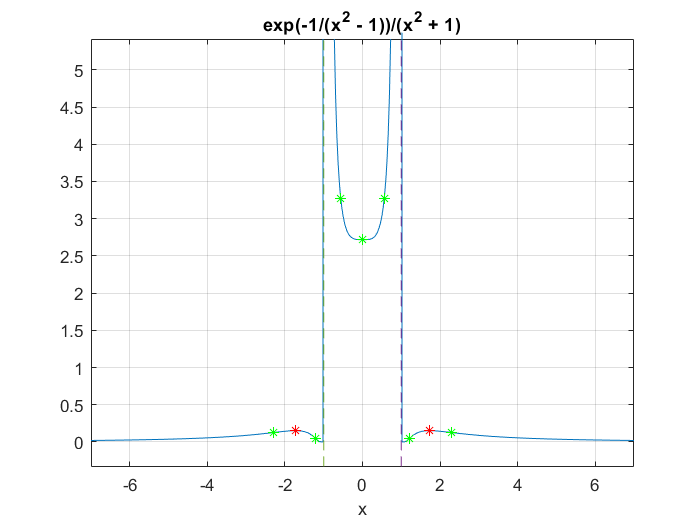

%%7
syms x;
f = exp(1/(1-x.^2))./(1+x^2);
ezplot(f,[-7,7]);
y = linspace(-1,20,100);
grid on;
hold on;
f_diff = diff(f);
b = solve(f_diff,0);
a = subs(f,x,b);
plot(b,a, "*r");
f_diff1 = diff(f_diff);
b1 =real (solve(f_diff1,0));
a1 = real(subs(f,x,b1));
plot(b1,a1,'*g');
plot(0*y+1,y,'--', 0*y-1,y,'--');
hold off;

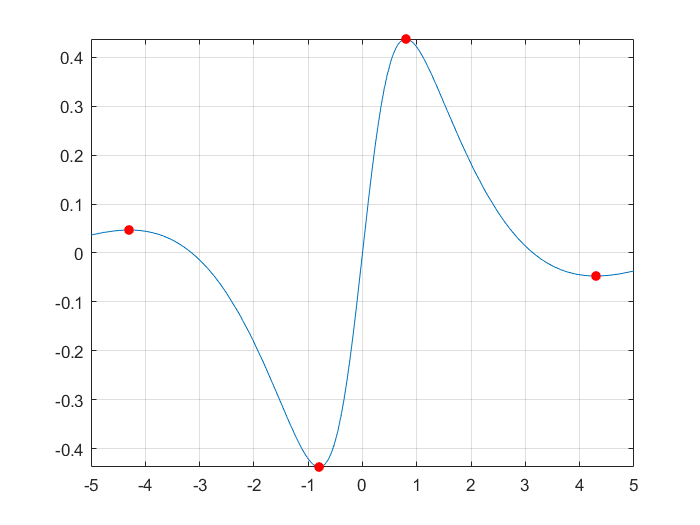

%% 8
syms x;
y = sin(x)/(x^2+1);
fplot(y);
hold on;
grid on;
X = -5:0.1:5;
Y = sin(X)./(X.^2+1);
F_min = islocalmin(Y);
plot(X(F_min), Y(F_min), 'r.', 'MarkerSize', 20);
F_max = islocalmax(Y);
plot(X(F_max), Y(F_max), 'r.', 'MarkerSize', 20);
hold off;